
clear variables;
[alldata,queries] = get_data_and_queries_32dim();

[gt_nns,gt_dists] = get_ground_truth_100_32();


pivots = [alldata(1:100,:) ; alldata(600:1000,:)];
%have 496 witnesses, calculate centiles more easily!
witnesses = alldata(101:596,:);
data = alldata(1001:end,:);


get thresholds per query

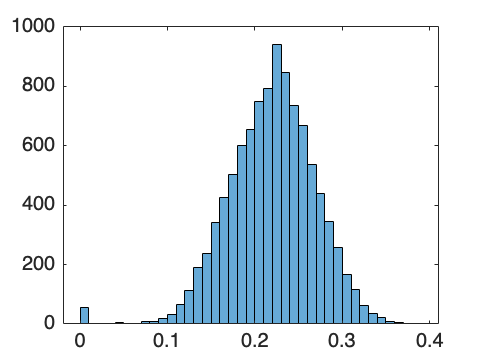


minDists = min(gt_dists,[],2);
thrDists = gt_dists(:,20);
histogram(minDists);

histogram(thrDists);


threshold = median(gt_dists(:,1));

there are zeros here which seems suspicious to me; some queries have multiple zero distances to the data... but maybe this is also true in the original data, maybe there are multiple copies of some images. will check... indeed the original data has some very, very small distances eg 10_-4

create a pile of  embeddings, no overlap among pivot points


medianExclusions = zeros(1,10);

for embeddingDimension = 2 : 10
    no_of_partitions = 50;

    all_partitions = getNdPartitions(pivots,no_of_partitions,embeddingDimension);


    best_excluded = zeros(1,size(data,1));
    outliers_cum = zeros(no_of_partitions,1);

    for i = 1 : no_of_partitions
        part = all_partitions(i);
        part = part.setWitnesses(witnesses);
        excluded = part.getExcluded(data,threshold);
        best_excluded = max(best_excluded,excluded);
    end

    histogram(best_excluded ./ size(witnesses,1),100);
    medianExclusions(embeddingDimension) = median(best_excluded ./ size(witnesses,1))
end


plot(2:1:10,medianExclusions(2:10));

look for correlation between the best pivot pair for some data, and the individual centiles


no_of_partitions = 50;
all_partitions = getNdPartitions(pivots,no_of_partitions,2);
set_partitions(1:no_of_partitions) = partition;
for i = 1 : no_of_partitions
    set_partitions(i) = all_partitions(i).setWitnesses(witnesses);
end


best_excluded = zeros(1,size(data,1));
best_partition = zeros(1,size(data,1));
best_centile = zeros(1,size(data,1));

for i = 1 : no_of_partitions
    part = set_partitions(i);
    excluded = part.getExcluded(data,threshold);
    this_one_better = excluded > best_excluded;
    best_partition(this_one_better) = i;
    cents = part.getCentiles(data);
    best_centile(this_one_better) = cents(this_one_better);
    best_excluded = max(best_excluded,excluded);
end


ans =    -0.4667
   -0.3759
   -0.3652
   -0.3524
   -0.3435
   -0.3231
   -0.3110
   -0.3030
   -0.2983
   -0.2906


ans =     0.2786
    0.3262
    0.3554
    0.3963
    0.4093
    0.4163
    0.4302
    0.4366
    0.4416
    0.4474


ans =     0.0460
    0.1163
    0.1448
    0.1608
    0.1709
    0.1836
    0.2090
    0.2188
    0.2317
    0.2362


ans =    -0.3177
   -0.2092
   -0.1657
   -0.1474
   -0.1326
   -0.1241
   -0.1060
   -0.0974
   -0.0916
   -0.0885


ans =    -0.0060
    0.0364
    0.0562
    0.0650
    0.0802
    0.0873
    0.0974
    0.1030
    0.1077
    0.1117


ans =     0.1606
    0.2877
    0.3040
    0.3097
    0.3225
    0.3374
    0.3500
    0.3539
    0.3564
    0.3596


ans =     0.0391
    0.0880
    0.1274
    0.1466
    0.1506
    0.1649
    0.1818
    0.1904
    0.2084
    0.2125


ans =     0.1914
    0.2670
    0.2831
    0.3151
    0.3303
    0.3472
    0.3596
    0.3907
    0.3981
    0.4074


ans =    -0.1672
   -0.1309
   -0.1021
   -0.0911
   -0.0875
   -0.0812
   -0.0764
   -0.0713
   -0.0687
   -0.0582


ans =    -0.1402
   -0.0553
   -0.0190
   -0.0089
    0.0065
    0.0154
    0.0201
    0.0263
    0.0341
    0.0444


ans =     0.0135
    0.0622
    0.1276
    0.1463
    0.1655
    0.1708
    0.1783
    0.1846
    0.1898
    0.1933


ans =     0.1400
    0.2837
    0.2955
    0.3101
    0.3296
    0.3442
    0.3576
    0.3709
    0.3821
    0.3921


ans =     0.2233
    0.2764
    0.3234
    0.3494
    0.3605
    0.3790
    0.3862
    0.4038
    0.4210
    0.4283


ans =     0.1525
    0.2878
    0.3146
    0.3294
    0.3456
    0.3570
    0.3622
    0.3745
    0.3868
    0.3935


ans =    -0.0145
    0.0712
    0.0858
    0.1063
    0.1150
    0.1326
    0.1454
    0.1599
    0.1736
    0.1906


ans =    -0.0264
    0.0186
    0.0385
    0.0491
    0.0604
    0.0673
    0.0756
    0.0793
    0.0859
    0.0887


ans =    -0.3322
   -0.2437
   -0.2185
   -0.2094
   -0.1827
   -0.1612
   -0.1536
   -0.1449
   -0.1400
   -0.1359


ans =     0.2966
    0.3165
    0.3312
    0.3455
    0.3596
    0.3651
    0.3739
    0.3786
    0.3815
    0.3874


ans =    -0.1922
   -0.1465
   -0.1158
   -0.0992
   -0.0859
   -0.0766
   -0.0572
   -0.0473
   -0.0399
   -0.0298


ans =    -0.4560
   -0.4185
   -0.3971
   -0.3813
   -0.3614
   -0.3505
   -0.3395
   -0.3270
   -0.3217
   -0.3152


ans =    -0.0378
    0.0053
    0.0348
    0.0442
    0.0754
    0.0835
    0.0914
    0.0964
    0.1054
    0.1099


ans =     0.1873
    0.2691
    0.3103
    0.3145
    0.3314
    0.3379
    0.3486
    0.3648
    0.3699
    0.3748


ans =     0.1340
    0.1906
    0.2120
    0.2388
    0.2465
    0.2549
    0.2607
    0.2748
    0.2880
    0.2946


ans =    -0.0520
    0.0056
    0.0499
    0.0755
    0.1059
    0.1129
    0.1277
    0.1351
    0.1387
    0.1486


ans =    -0.4485
   -0.3855
   -0.3654
   -0.3405
   -0.3357
   -0.3292
   -0.3193
   -0.3150
   -0.3048
   -0.2972


ans =     0.0294
    0.0607
    0.0804
    0.1002
    0.1053
    0.1167
    0.1240
    0.1308
    0.1332
    0.1380


ans =    -0.0556
   -0.0059
    0.0287
    0.0453
    0.0660
    0.0766
    0.0843
    0.0938
    0.1094
    0.1200


ans =     0.2650
    0.3161
    0.3402
    0.3479
    0.3776
    0.3850
    0.3972
    0.4013
    0.4121
    0.4156


ans =     0.1804
    0.2345
    0.2526
    0.2725
    0.2885
    0.2947
    0.2995
    0.3084
    0.3225
    0.3268


ans =     0.2623
    0.3473
    0.3605
    0.3900
    0.4014
    0.4151
    0.4191
    0.4246
    0.4333
    0.4370


ans =    -0.0877
   -0.0210
    0.0037
    0.0152
    0.0257
    0.0401
    0.0612
    0.0724
    0.0820
    0.0874


ans =    -0.4067
   -0.3670
   -0.3392
   -0.3123
   -0.2967
   -0.2942
   -0.2913
   -0.2854
   -0.2775
   -0.2703


ans =    -0.1602
   -0.1258
   -0.0938
   -0.0679
   -0.0566
   -0.0427
   -0.0398
   -0.0303
   -0.0199
   -0.0120


ans =     0.2512
    0.3708
    0.3972
    0.4061
    0.4147
    0.4310
    0.4376
    0.4519
    0.4580
    0.4671


ans =     0.0302
    0.1549
    0.1857
    0.2103
    0.2331
    0.2415
    0.2454
    0.2516
    0.2575
    0.2624


ans =    -0.0735
   -0.0202
   -0.0072
    0.0086
    0.0274
    0.0341
    0.0426
    0.0458
    0.0519
    0.0571


ans =    -0.0302
    0.0713
    0.0905
    0.1109
    0.1172
    0.1310
    0.1459
    0.1605
    0.1648
    0.1684


ans =     0.1059
    0.1586
    0.1690
    0.1813
    0.1931
    0.1978
    0.2033
    0.2072
    0.2128
    0.2153


ans =     0.0128
    0.0251
    0.0443
    0.0633
    0.0746
    0.0786
    0.0837
    0.0914
    0.0965
    0.0998


ans =     0.0242
    0.0731
    0.0870
    0.0987
    0.1134
    0.1250
    0.1324
    0.1385
    0.1448
    0.1580


ans =    -0.2580
   -0.1807
   -0.1494
   -0.1388
   -0.1284
   -0.1221
   -0.1121
   -0.1042
   -0.1004
   -0.0953


ans =     0.0329
    0.0585
    0.0786
    0.0970
    0.1142
    0.1230
    0.1304
    0.1368
    0.1445
    0.1531


ans =     0.3233
    0.3512
    0.3823
    0.4067
    0.4303
    0.4349
    0.4451
    0.4475
    0.4502
    0.4565


ans =     0.0629
    0.1055
    0.1157
    0.1299
    0.1395
    0.1462
    0.1525
    0.1596
    0.1676
    0.1730


ans =    -0.1759
   -0.0955
   -0.0713
   -0.0616
   -0.0405
   -0.0305
   -0.0164
   -0.0115
   -0.0052
    0.0013


ans =     0.0281
    0.1095
    0.1294
    0.1568
    0.1694
    0.1781
    0.2028
    0.2156
    0.2356
    0.2473


ans =    -0.0195
    0.0774
    0.1057
    0.1218
    0.1316
    0.1392
    0.1489
    0.1544
    0.1588
    0.1683


ans =     0.2203
    0.3109
    0.3664
    0.3879
    0.4283
    0.4449
    0.4742
    0.4920
    0.4968
    0.5098


ans =     0.3005
    0.3728
    0.3999
    0.4068
    0.4113
    0.4218
    0.4292
    0.4323
    0.4376
    0.4442


ans =     0.1152
    0.1526
    0.1780
    0.1913
    0.1967
    0.2056
    0.2093
    0.2181
    0.2251
    0.2366



histogram(set_partitions.centiles(100) - set_partitions.centiles(1));

Intermediate dot '.' indexing produced a comma-separated list with 50 values, but it must produce a single value when followed by subsequent indexing operations.

Related documentation



histogram(best_partition);
histogram(best_centile);

scatter(best_centile(1:500),best_excluded(1:500));
scatter(best_excluded(1:500),best_centile(1:500));



that all looks quite convincing! so rerun the earlier experiment but find the best/worst centile, then use that to calcualte exclusions


best_partition = zeros(size(data,1),1);
best_centile(1:size(data,1),1) = 50;

for i = 1 : no_of_partitions
    part = set_partitions(i);
    cents = part.getCentiles(data);
    this_one_better = abs(50-cents) > abs(50-best_centile);
    best_centile(this_one_better) = cents(this_one_better);
    best_partition(this_one_better) = i;
end








simp = part1.nsimp;
part1 = part1.setWitnesses(witnesses);
proj = part1.proj;

figure;
hold on;
pivs = [0,0;euc(pivots(1,:),pivots(2,:)),0];
scatter(proj(:,1),proj(:,2));
scatter(pivs(:,1),pivs(:,2),"red");
hold off;


% figure;
% hold on;
% scatter3(proj(:,1),proj(:,2),proj(:,3))
% scatter3(pivots(1:3,1),pivots(1:3,2),pivots(1:3,3),"red");
% hold off;




now try to measure the value of the spread along the 1st principle component...

figure;
hold on;
plot(1:1:496,sort(adjdata(:,1)));
plot(1:1:496, sort(proj(:,1)));
legend("pc","raw");
hold off;


mn = median(proj(:,1));
diffs = proj(:,1) - mn;
histogram(diffs,"NumBins",100);

mn = median(adjdata(:,1));
diffs = adjdata(:,1) - mn;
histogram(diffs,"NumBins",100);




calculate the centiles


xs = sort(adjdata(:,1));
centiles = xs(1:5:496);
figure;
plot(1:1:100,centiles);


function partitions = get2DPartitions(pivots,no_of_partitions)

partitions(1:no_of_partitions) = partition;
for i = 1 : no_of_partitions
    pivs = [pivots((i-1)*2+1,:) ; pivots((i-1)*2 + 2,:)];
    this_part = partition(pivs,2,@euc);
    partitions(i) = this_part;
end

end

function partitions = get3DPartitions(pivots,no_of_partitions)

partitions(1:no_of_partitions) = partition;
for i = 1 : no_of_partitions
    pivs = [ pivots((i-1)*3+1,:) ; pivots((i-1)*3+2,:); pivots((i-1)*3+3,:)];
    this_part = partition(pivs,3,@euc);
    partitions(i) = this_part;
end

end

function partitions = getNdPartitions(pivots, no_of_partitions, dimensions)

partitions(1:no_of_partitions) = partition;
for i = 1 : no_of_partitions
    pivs = pivots((i-1)*dimensions+1:(i-1)*dimensions+dimensions,:);
    this_part = partition(pivs,dimensions,@euc);
    partitions(i) = this_part;
end

end

